# Linear regression, GLMs and model comparison

To explore how neuronal firing is modulated by an independent variable (be it an external stimuli or another brain signal), a variety of approaches can be employed. Multiple linear regression and generalized linear models are among the most commonly used method to estimate the selectivity of neurons to those stimuli.

Given the complexity of neural activity and its susceptibility to various factors, certain models may capture these intricacies more effectively. Model comparisons offer a quantitative way to assess how well each model explains the observed data. The goal of model comparison is to pinpoint which model strikes the right balance between simplicity and accuracy. It helps us avoid issues like overfitting (when a model fits noise in the data) or underfitting (when a model oversimplifies the underlying pattern). Ultimately, model comparisons guide us in selecting the model that yields the most valuable insights into how neurons process information.

This tuorial is divided into three parts:

- mapping place fields under a linear model assumption

- mapping the selectivity of place cells with a generalized linear model approach

- comparison of place fields across experimental conditions

## 2.1. The classical way of mapping place fields

This is the most common method used to estimate place fields. It consists in a series of steps which aim to compute the average firing rate of a place cell as a function of the positions of the animal. You have already been familiarized with these steps in tutorial 1: first, behavioral data, which tracks the movement of the animal, is synchronized with the corresponding neural activity. Then, the environment is divided into discrete spatial bins. Each bin represents a small area within the environment. The size of the bins can vary depending on the resolution you desire for your place fields. Finally, the count of spikes that occurred when the animal was within a specific bin is tallied (see function ***ComputeMap***). This count is then divided by the amount of time the animal spent in that particular bin (*occupancy map*). To create a clearer visualization, maps are usually smoothed with a gaussian (see ***GaussianSmooth***). This smoothing reduces noise and provides a smoother transition between adjacent spatial bins. 

To identify place fields, we have to define some statistics. Here we'll illustrate two different approaches: comparing the tuning curve selectivity to a shuffle control distribution or testing whether the likelihood of the place field model is better than a reduced model that does not account for positions to explain the cell's firing.

The analyses described in this section can be run by calling the following set of functions:

%define parameters for place fields estimation
mapsparams = SetMapsParams(Nav,Spk);

%estimate 1D place fields and related statistics
mapsparams.Xvariablename = 'Xpos';
mapsparams.Xbinedges = 0:4:100;
mapsparams.XsmthNbins = 1;
mapsparams.Yvariablename = [];
Maps1D = MapsAnalysis(Nav, Spk.spikeTrain, mapsparams);

%estimate 2D place fields and related statistics
mapsparams.Yvariablename = 'XDir';
mapsparams.Ybinedges = [-2 0 2];
mapsparams.YsmthNbins = 1;
Maps2D = MapsAnalysis(Nav, Spk.spikeTrain, mapsparams);

*Some useful function that you will also find here are: ****ComputeMap.m, GaussianSmooth.m***

#### 2.1.1 Loading and preprocessing the behavioral and spiking data (as done in Tutorial1)

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

#### 2.1.2 Parameters for estimating place fields

Defining a set of parameters needed to compute place fields such as the bin size used for discretizing the X variable or the experiemental conditions over which place fields should be estimated.

%Experimental conditions over which place fields will be estimated
mapsparams.subset.Condition = [1 3 5];%values to select for Nav.Condition
mapsparams.subset.Condition_op = 'ismember';%operator to apply on Nav.Condition with values above

%Directions over which place fields will be estimated
mapsparams.subset.XDir = [-1 1];
mapsparams.subset.XDir_op = 'ismember';

%lap types over which place fields will be estimated
mapsparams.subset.laptype = [-1 0 1];
mapsparams.subset.laptype_op = 'ismember';

%Minimum speed threshold over which place fields will be computed
mapsparams.subset.Spd =  2.5;
mapsparams.subset.Spd_op = '>=';

%Subset of cells for which place fields will be computed
mapsparams.cellidx = true(1, size(Spk.spikeTrain, 2));

%Sampling rate of the data
mapsparams.sampleRate = 1 / mean(diff(Nav.sampleTimes));

%Name of the field in the structure Nav that we will use as X dependent
%variable
mapsparams.Xvariablename = 'Xpos';

%Edges of position bins used to discretize positions
mapsparams.Xbinedges = 0 : 4 : 100;

%Size of the gaussian window for smoothing place fields (in bins).
mapsparams.XsmthNbins = 1;

%Occupancy threshold above which positions are included in the place field
%estimate (in seconds)
mapsparams.occ_th = 0;

%Minimal number of spikes to consider a cell
mapsparams.nspk_th = 0;

%Number of shuffle controls to perform
mapsparams.nShuffle = 100;

%Number of folds to consider for cross-validation
mapsparams.kfold = 10;

This set of parameters can be obtained by calling SetMapsParams**.m**

mapsparams = SetMapsParams(Nav,Spk);

#### 2.1.3 Compute place fields for all neurons (1D)

We will start by focusing on place fields when the animal is moving from left to right.

If you remember things from Tutorial 1, we first need to subset the data and keep only indices that correspond to the condition and criteria that we defined in mapsparams.

%We want only 1D place fields. So we modify mapsparams accordingly.
mapsparams.Xvariablename = 'Xpos';
mapsparams.Xbinedges = 0:4:100;
mapsparams.XsmthNbins = 1;
mapsparams.Yvariablename = [];

%We want left to right direction (Nav.Xdir = 1) so let's first change this
%parameter in the mapsparams structure. (We had [-1 1] originally.
mapsparams.subset.XDir = 1;
mapsparams.subset.XDir_op = '==';

%Selecting time indices over which to compute maps, according to parameters
%defined in mapsparams.subset
tidx = true(size(Nav.Xpos));
pnames = fieldnames(mapsparams.subset);
fnames = fieldnames(Nav);
for i = 1:numel(pnames)
    if ismember(pnames{i},fnames)
        fn = str2func(mapsparams.subset.([pnames{i} '_op']));
        tidx = tidx & fn(Nav.(pnames{i}), mapsparams.subset.(pnames{i}));
    end
end

%Selecting time indices where X and Y are in the range of bins
tidx = tidx &...
       Nav.X >= mapsparams.Xbinedges(1) & Nav.X <= mapsparams.Xbinedges(end) &...
       ~isnan(Nav.X);

%Selecting cell indices for which we'll run the analysis
cellidx = find(mapsparams.cellidx & sum(Spk.spikeTrain(tidx,:), 1) > mapsparams.nspk_th);

%Subsetting Spk.spikeTrain and Nav.Xpos
spikeTrain = Spk.spikeTrain(tidx,cellidx);
Xpos = Nav.Xpos(tidx);

Then, we have to compute the occupancy map as done in Tutorial1, using **ComputeMap.m** and **GaussianSmooth.m**

%number of position bins
nbins = numel(mapsparams.Xbinedges) - 1;

%Discretizing position vectors according to mapsparams.binedges
Xpos_discrete = discretize(Xpos, mapsparams.Xbinedges);

%Computing occupancy map (same for all cells)
flat =  1/mapsparams.sampleRate * ones(size(Xpos_discrete));
occmap = ComputeMap(Xpos_discrete, [], flat, nbins, []);

%Removing occupancy for positions below the occupancy threshold
occmap(occmap <= mapsparams.occ_th) = NaN;

%Smoothing the occupancy map with a gaussian window (mapsparams.smthNbins
%of sd)
occmap = GaussianSmooth(occmap, mapsparams.XsmthNbins);

Now, we compute the spike count maps similarly.

%number of cells selected for place field analysis
ncells = size(spikeTrain, 2);

%Initializing the spike count map
scmap = NaN(ncells, nbins);

%Computing and smoothing spike count map for each cell
for icell = 1:ncells
    %raw spike count map
    scmap(icell,:) = ComputeMap(Xpos_discrete, [], spikeTrain(:,icell), nbins, []);
    %Removing values of scmap where occupancy is too low
    scmap(icell,isnan(occmap)) = NaN;
    %Smoothing with a Gaussian (mapsparams.XsmthNbins of s.d.)
    scmap(icell,:) = GaussianSmooth(scmap(icell,:), mapsparams.XsmthNbins);
end

Finally, calculate the place field of all cells from the spike count maps (scmap) and the occupancy maps (occmap).

%Calculating the place field maps by dividing scmap and occmap
mapX = scmap ./ occmap;

This method to estimate place fields can be run by calling MapsAnalysis**.m**, which returns results of this place field estimation into a structure. 

Use that function to compute place fields for left to right and right to left directions.

%Computing left to right place fields
%Changing mapsparams.dir for left to right direction
mapsparams.subset.XDir = 1;
mapsparams.subset.XDir_op = '==';

%Running the complete 1D map analysis
Maps1 = MapsAnalysis(Nav, Spk.spikeTrain, mapsparams);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 36 workers.



%Same for right to left place fields
%Changing mapsparams.subset.XDir for left to right direction
mapsparams.subset.XDir = -1;
mapsparams.subset.XDir_op = '==';
%Running the complete 1D map analysis
Maps2 = MapsAnalysis(Nav, Spk.spikeTrain, mapsparams);

We will now take the place fields of all cells and order them according to their peak position of firing. For visualization purpose, we will normalize maps between 0 and max firing rate. This helps us create what we call population spatial maps. These maps offer a complete picture of how place cells act all over the recording area. As we carried out our analysis independently for both rightward and leftward movements, this illustrates that place cells can exhibit spatial activity that is specific to particular directions

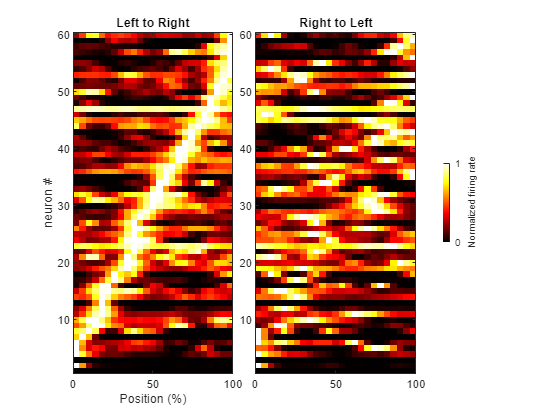

%Detecting max firing rate and peak position
[maxLtoR, peakidx] = max(Maps1.map, [], 3);
[maxRtoL, ~] = max(Maps2.map, [], 3);

%Normalizing place fields from 0 to max firing rate
mapXLtoR = squeeze(Maps1.map ./ maxLtoR);
mapXRtoL = squeeze(Maps2.map ./ maxRtoL);

%Reordering place fields according to peak position (estimated from L to R
%place fields).
[~, sortidx] = sort(peakidx, 'ascend');
mapXLtoR = mapXLtoR(sortidx,:);
mapXRtoL = mapXRtoL(sortidx,:);

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + diff(mapsparams.Xbinedges) / 2;
subplot(1,5,[1 2]);
imagesc(bincenters, [], mapXLtoR);
subplot(1,5,[3 4]);
imagesc(bincenters, [], mapXRtoL);
colormap(hot);

%labels title etc
subplot(1,5,[1 2]);
set(gca,'YDir','normal')
xlabel('Position (%)');
ylabel('neuron #');
title('Left to Right');

subplot(1,5,[3 4]);
set(gca,'YDir','normal')
title('Right to Left');

subplot(3,5,10);
set(gca,'Visible','off')
c = colorbar('Ticks', [0 1], 'location', 'west');
c.Label.String = 'Normalized firing rate';

### 2.1.4 Compute place fields for all neurons (2D)

Mapping place fields in two dimensions, as opposed to a single dimension, offers a more comprehensive and nuanced understanding of the  encoding of spatial components by place cells. Such multidimensional place field mapping provides a more holistic view of how neurons encode multiple variable together. For instance, in a 2D arena, incorporating both X and Y axes is crucial in estimating how place cells encode positions (see Tutorial 1). Here, we will estimate the place fields of our neurons along X posiitons and directions of movement, all at once. The procedure is a very simple extension of the 1D case detailed above, so we will go quickly through it.

Just as before, we first start by subsetting Nav.Xpos, Nav.XDir and Spk.spikeTrain according to the criteria defined in mapsparams

%We want Direction x Position place fields. So we modify mapsparams accordingly.
mapsparams.Xvariablename = 'Xpos';
mapsparams.Xbinedges = 0:4:100;
mapsparams.XsmthNbins = 1;

mapsparams.Yvariablename = 'XDir';
mapsparams.Ybinedges = [-2 0 2];
mapsparams.YsmthNbins = 0;

%We want both direction so let's change the corresponding
%parameter in the mapsparams structure (We had [-1 1] originally).
mapsparams.subset.XDir = [-1 1];
mapsparams.subset.XDir_op = 'ismember';

%Selecting time indices over which to compute maps, according to parameters
%defined in mapsparams.subset
tidx = true(size(Nav.Xpos));
pnames = fieldnames(mapsparams.subset);
fnames = fieldnames(Nav);
for i = 1:numel(pnames)
    if ismember(pnames{i},fnames)
        fn = str2func(mapsparams.subset.([pnames{i} '_op']));
        tidx = tidx & fn(Nav.(pnames{i}), mapsparams.subset.(pnames{i}));
    end
end

%Selecting time indices where X and Y are in the range of bins
tidx = tidx &...
       Nav.Xpos >= mapsparams.Xbinedges(1) & Nav.Xpos <= mapsparams.Xbinedges(end) &...
       Nav.XDir >= mapsparams.Ybinedges(1) & Nav.XDir <= mapsparams.Ybinedges(end) &...
       ~isnan(Nav.Xpos) & ~isnan(Nav.XDir);
   
cellidx = find(mapsparams.cellidx & sum(Spk.spikeTrain(tidx,:), 1) > mapsparams.nspk_th);

%Subsetting spikeTrain, Xpos and XDir.
spikeTrain = Spk.spikeTrain(tidx,cellidx);
Xpos = Nav.Xpos(tidx);
Dir = Nav.XDir(tidx);

Then we compute the occupancy maps as done previously, but this time using** Compute2DMap.m **and **GaussianSmooth.m**

%number of position bins
nXbins = numel(mapsparams.Xbinedges) - 1;

%number of direction bins
nLRbins = 2;

%No smoothing across directions
LRsmthNbins = 0;

%Discretizing position vectors according to mapsparams.Xbinedges
Xpos_discrete = discretize(Xpos, mapsparams.Xbinedges);

%Discretizing XDir so that 2 corresponds to left to right (ie
%Nav.XDir = 1) and 1 corresponds to right to left (ie Nav.XDir = -1).
Dir_discrete = NaN(size(Dir));
Dir_discrete(Dir == -1) = 1;
Dir_discrete(Dir == 1) = 2;

%Computing occupancy map (same for all cells)
flat =  1/mapsparams.sampleRate * ones(size(Xpos_discrete));
occmap = ComputeMap(Xpos_discrete, Dir_discrete, flat, nXbins, nLRbins);

%Removing occupancy for positions below the occupancy threshold
occmap(occmap <= mapsparams.occ_th) = NaN;

%Smoothing the occupancy map with a 2D gaussian window
occmap = GaussianSmooth(occmap, [LRsmthNbins mapsparams.XsmthNbins]);

Now computing the spike count maps in a similar fashion.

%number of cells selected for place field analysis
ncells = size(spikeTrain, 2);

%Initializing the spike count map
scmap = NaN(ncells, nLRbins, nXbins);

%Computing and smoothing spike count map for each cell
for icell = 1:ncells
    scmap(icell,:,:) = ComputeMap(Xpos_discrete, Dir_discrete, spikeTrain(:,icell), nXbins, nLRbins);
    scmap(icell,isnan(occmap)) = NaN;
    scmap(icell,:,:) = GaussianSmooth(squeeze(scmap(icell,:,:)), [LRsmthNbins mapsparams.XsmthNbins]);
end

Finally, calculating the place field of all cells by dividing the spike count map (scmap) with the occupancy (occmap).

%Calculating the place field x direction maps by dividing scmap and occmap
occmap = permute(occmap, [3 1 2]);%permuting dimension for element-wise division
mapXY = scmap ./ occmap;
occmap = squeeze(occmap);%reshaping occmap as before

All this code can be run by calling MapsAnalysis**.m**

mapsparams = SetMapsParams(Nav,Spk);
Maps = MapsAnalysis(Nav, Spk.spikeTrain, mapsparams);

Have a look at the Maps structure returned by MapsAnalysis**.m **and find out where the maps are (use the help).

To make sure that we did everything correct, let's plot again the population place fields in both direction (same code as for the previous figure).

%Detecting max firing rate and peak position
[maxLtoR, peakidx] = max(Maps.map(:,2,:), [], 3);
[maxRtoL, ~] = max(Maps.map(:,1,:), [], 3);

%Normalizing place fields from 0 to max firing rate
mapXLtoR = squeeze(Maps.map(:,2,:)) ./ maxLtoR;
mapXRtoL = squeeze(Maps.map(:,1,:)) ./ maxRtoL;

%Reordering place fields according to peak position (estimated from L to R
%place fields).
[~, sortidx] = sort(peakidx, 'ascend');
mapXLtoR = mapXLtoR(sortidx,:);
mapXRtoL = mapXRtoL(sortidx,:);

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + diff(mapsparams.Xbinedges) / 2;
subplot(1,5,[1 2]);
imagesc(bincenters, [], mapXLtoR);
subplot(1,5,[3 4]);
imagesc(bincenters, [], mapXRtoL);
colormap(hot);

%labels title etc
subplot(1,5,[1 2]);
set(gca,'YDir','normal')
xlabel('Position (%)');
ylabel('neuron #');
title('Left to Right');

subplot(1,5,[3 4]);
set(gca,'YDir','normal')
title('Right to Left');

subplot(3,5,10);
set(gca,'Visible','off')
c = colorbar('Ticks', [0 1], 'location', 'west');
c.Label.String = 'Normalized firing rate';

### 2.1.5 Place field significance

The next step involves assessing the selectivity of place fields using some quantitative metrics. The* spatial information* metric assesses the neuron's encoding of location, while the *sparsity* of the tuning curve gauges how concentrated the firing pattern is around a particular spot. The *selectivity index *captures the modulation of the firing pattern, and the *directionality index* evaluates preference for movement directions. To calculate these metrics, we'll use the following functions (**getSpatialinfo.m**, **getSparsity.m**, **getSelectivity.m**, **getDirectionality.m**).

%Initilizing the vectors
SI = NaN(ncells, 1);
SparsityIndex = NaN(ncells, 1);
SelectivityIndex = NaN(ncells, 1);
DirectionalityIndex = NaN(ncells, 1);

%Calculating all metrics for each cell
for icell = 1:ncells
    SI(icell) = getSpatialinfo(mapXY(icell,:,:), occmap);
    SparsityIndex(icell) = getSparsity(mapXY(icell,:,:), occmap);
    SelectivityIndex(icell) = getSelectivity(mapXY(icell,:,:));
    DirectionalityIndex(icell) = getDirectionality(mapXY(icell,:,1), mapXY(icell,:,2));
end

To measure the significance of the seletivity of a neurons to positions, we can now comparing the metrics obtained from the actual data with the same metrics measured after shuffling the spiking data with respect to positions. To maintain the original dynamics of shuffle control, we will permute the data by a random time delay. This process is repeated multiple times to create a distribution of random metrics. We then compare the metrics obtained from the actual cells with the statistically significant threshold determined by the distribution of random metrics.

%Computing shuffle controls by randomly shifting time bins of positions and
%calculate the selectivity metrics for each shuffle control

SI_Shf = NaN(ncells, mapsparams.nShuffle);
SparsityIndex_Shf = NaN(ncells, mapsparams.nShuffle);
SelectivityIndex_Shf = NaN(ncells, mapsparams.nShuffle);
DirectionalityIndex_Shf = NaN(ncells, mapsparams.nShuffle);

%Initializing the random number generator for reproducibility purposes
s = RandStream('mt19937ar','Seed',0);

%number of data points
ntimepts = size(spikeTrain, 1);

%Calculating the place field for each shuffle permutation
for iperm  = 1:mapsparams.nShuffle
    tshift = randi(s,ntimepts - 2 * mapsparams.sampleRate) + 1 * mapsparams.sampleRate;
    Xpos_discrete_shf = circshift(Xpos_discrete, round(tshift));
    Dir_discrete_shf = circshift(Dir_discrete, round(tshift));
    for icell = 1:ncells
        scmap_shf = ComputeMap(Xpos_discrete_shf, Dir_discrete_shf, spikeTrain(:,icell), nXbins, nLRbins);
        scmap_shf(isnan(occmap)) = NaN;
        scmap_shf = GaussianSmooth(scmap_shf, [LRsmthNbins mapsparams.XsmthNbins]);
        mapX_shf = scmap_shf ./ occmap;
        
        %saving only the spatial selectivity metrics for each permutation
        SI_Shf(icell,iperm) = getSpatialinfo(mapX_shf, occmap);
        SparsityIndex_Shf(icell,iperm) = getSparsity(mapX_shf, occmap);
        SelectivityIndex_Shf(icell,iperm) = getSelectivity(mapX_shf);
        DirectionalityIndex_Shf(icell,iperm) = getDirectionality(mapX_shf(:,1), mapX_shf(:,2));
    end
end

%Computing p-values from the distribution of selectivity measures obtained
%from the shuffle controls
SI_pval = sum(SI_Shf > SI, 2) / mapsparams.nShuffle;
SparsityIndex_pval = sum(SparsityIndex_Shf > SparsityIndex, 2) / mapsparams.nShuffle;
SelectivityIndex_pval = sum(SelectivityIndex_Shf > SelectivityIndex, 2) / mapsparams.nShuffle;
DirectionalityIndex_pval = sum(DirectionalityIndex_Shf > DirectionalityIndex, 2) / mapsparams.nShuffle;

Another way to assess the significance of those place fields is by estimating how much adding position to the model improves its ability to explain the neuron's response. This is called model comparison and it enables us to determine which model best captures the underlying patterns in the data. Cross-validation enhances the reliability of model comparison by rigorously assessing model performance on unseen data. By partitioning the dataset into training and testing subsets, cross-validation prevents overfitting, i.e. where a model may perform well on training data but poorly on new data. This approach ensures that the chosen model is not only adept at explaining the observed data but also generalizes well to new instances. Thus, conducting model comparison on cross-validated data provides a robust framework for selecting the most accurate and meaningful representation of complex neural processes.

As a first step, we thus need to compute spiking responses predicted by the place field model and to do so, we will use a k-fold cross-validation apparoch. K-fold cross-validation is a method used to assess the performance of a model by dividing a dataset into "k" subsets. The model is trained on "k-1" subsets and tested on the remaining fold in each iteration. This process is repeated "k" times, allowing for a comprehensive evaluation of the model's predictive ability over the entire dataset.

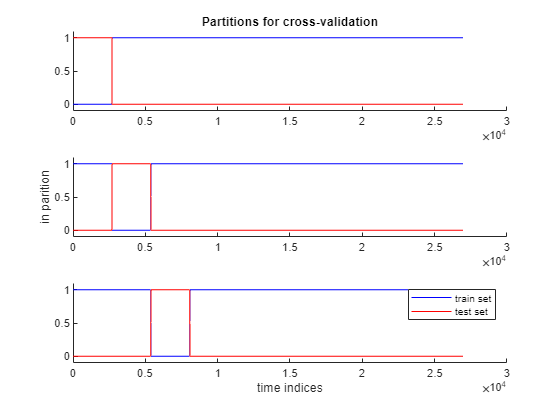

%Defining a partition of the data for k-fold cross-validation
cv = crossvalPartition(ntimepts, mapsparams.kfold);

%Plotting the first three partitions
figure;
for k = 1:3
    subplot(3,1,k);
    plot(cv.trainsets{k},'b');
    hold on;plot(cv.testsets{k},'r');
    set(gca,'Ylim',[-0.1 1.1],'box', 'off')
    if k == 3
        xlabel('time indices')
        legend({'train set', 'test set'})
    end
    if k == 2
        ylabel('in parition')
    end
    if k == 1
        title('Partitions for cross-validation')
    end
end

Now, we will calculate spike train predictions from place fields using this k-fold partition. To do that, we iterate through each fold, calculating the place fields on data from the training sets and predicting the spike train from the place fields on the testsets.

Let's first estimate place fields on each training set from the k-fold partitions. 

%Computing the spike train predicted from the place field using k-fold 
%cross-validation
mapXY_cv = NaN(ncells, nLRbins, nXbins, mapsparams.kfold);
for i = 1:mapsparams.kfold
    %Subsetting Xpos and spiketrain according to the train set of the
    %current fold
    Xtraining = Xpos_discrete(cv.trainsets{i});
    Dirtraining = Dir_discrete(cv.trainsets{i});
    Spktraining = spikeTrain(cv.trainsets{i},:);
    
    %Computing occupancy map for the current fold
    flat = 1/mapsparams.sampleRate * ones(size(Xtraining));
    occmap_cv = ComputeMap(Xtraining, Dirtraining, flat, nXbins, nLRbins);
    occmap_cv(occmap_cv <= mapsparams.occ_th) = NaN;
    occmap_cv = GaussianSmooth(occmap_cv, [LRsmthNbins mapsparams.XsmthNbins]);
    
    %Computing the spike count map and place field of each cell for the
    %current fold
    for icell = 1:ncells
        scmap_cv = ComputeMap(Xtraining, Dirtraining, Spktraining(:,icell), nXbins, nLRbins);
        scmap_cv(isnan(occmap_cv)) = NaN;
        scmap_cv = GaussianSmooth(scmap_cv, [LRsmthNbins mapsparams.XsmthNbins]);
        mapXY_cv(icell,:,:,i) = scmap_cv ./ occmap_cv;
    end
end

Now use the place fields computed from the train sets to predict the response on the test set for each fold

Ypred = NaN(ntimepts,ncells);
for i = 1:mapsparams.kfold
    %Subsetting Xpos and Dir according to the test set of the current fold
    Xtest = Xpos_discrete(cv.testsets{i});
    Dirtest = Dir_discrete(cv.testsets{i});
    
    %Computing the spike train predicted on the test set from the place 
    %computed from the train set
    for icell = 1:ncells
        XDiridx = sub2ind([ncells, nLRbins, nXbins, mapsparams.kfold], icell*ones(size(Xtest)), Dirtest, Xtest, i*ones(size(Xtest)));
        Ypred(cv.testsets{i},icell) = mapXY_cv(XDiridx) / mapsparams.sampleRate;%(Check here)
    end
end

Let's plot the predicted and actual responses for cell #18 together with the position of the animal for the first 40 seconds

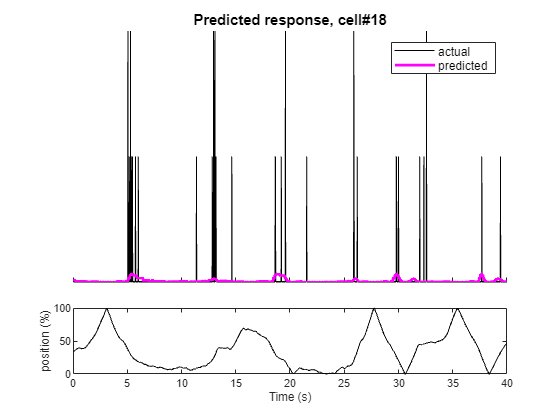

figure;
cellnum = 18;

%time indices of the first 40 seconds
idx = 1:40 * loadparams.sampleRate;

%Plotting predicted and actual responses
subplot(4, 1, 1:3);
plot(idx / loadparams.sampleRate, spikeTrain(idx,cellidx == cellnum),'k');
hold on;plot(idx / loadparams.sampleRate, Ypred(idx,cellidx == cellnum),'m', 'linewidth', 2);

%Plotting the position of the animal for the same time bins
subplot(4, 1, 4);
plot(idx / loadparams.sampleRate, Xpos(idx),'k');

%Legend, title, labels etc
subplot(4, 1, 1:3);
legend({'actual', 'predicted'})
set(gca,'Box','off', 'XtickLabel', [], 'Ytick',[], 'YColor', 'none')
title('Predicted response, cell#18')
subplot(4, 1, 4);
xlabel('Time (s)')
ylabel('position (%)')

Keep in mind that the ultimate objective of generating spike trains predicted by the place field model is to evaluate whether this model provides a more effective explanation for neural firing compared to a model that does not consider position as a predictor of the neuron's response. To achieve this, we must proceed by calculating the neuron's response under the assumption of a position-independent model, where the cell is assumed to exhibit a constant mean firing rate.

%Computing the spike train predicted from the mean firing rate of the 
%cell using the same k-fold partition as above
Ypred_cst = NaN(ntimepts,ncells);
for i = 1:mapsparams.kfold
    for icell = 1:ncells
        Ypred_cst(cv.testsets{i},icell) = nanmean(spikeTrain(cv.trainsets{i},icell));
    end
end

Compute the log likelihood for both the place field model and the constant mean model based on the predicted responses.

%Computing the percentage of explained variance and the log likelihood from
%the predicted responses.
EV = NaN(ncells,1);
LLH = NaN(ncells,1);
EV_cst = NaN(ncells,1);
LLH_cst = NaN(ncells,1);
for icell = 1:ncells
    %Percentage of explained variance for the place field model
    EV(icell) =  computeEV(spikeTrain(:, icell), Ypred(:, icell));
    %Log likelihood for the place field model
    LLH(icell) = computeLLH_normal(spikeTrain(:, icell), Ypred(:, icell));

    %Percentage of explained variance for the constant mean model
    EV_cst(icell) =  computeEV(spikeTrain(:, icell), Ypred_cst(:, icell));
    %Log likelihood for the constant mean model
    LLH_cst(icell) = computeLLH_normal(spikeTrain(:, icell), Ypred_cst(:, icell));
end

A method to assess the significance of incorporating positions into the model is to compare the log likelihood between the place field model and the constant mean model through a likelihood ratio test.

%Comparing the place field model to the constant mean model by performing a
%likelihood ratio test
LLH_pval = NaN(ncells,1);
goodidx = LLH > LLH_cst;
LLH_pval(~goodidx) = 1;

%difference of degree of freedom between the two models.
dof = sum(occmap(:) > 0) - 1;

%Likelihood ratio test for cells which have a higher LLH for the place
%field model (the other one are definitely not significant).
[~, LLH_pval(goodidx)] = lratiotest(LLH(goodidx), LLH_cst(goodidx), dof);

A valuable aspect of having computed the cross-validated place fields is the ability to derive a Jackknife estimate of the standard error from the k-fold cross-validated place fields. This estimation is based on assessing the difference between  place field of each individual fold and the overall mean place field. 

%Computing the Jacknife estimate of the standard error
mapXY_SE = sqrt((mapsparams.kfold - 1)./mapsparams.kfold * sum((mapXY_cv - mapXY).^2, 4));

All this code is also run in MapsAnalysis**.m**. 

Have a look at the Maps structure returned by MapsAnalysis**.m, **find out where these statistics are stored adn estimate the fraction of pyramidal cells that have a significant significant place field in terms of prediction accuracy.

Plot the place fields of neurons that are significant and those that are not (using P-value = 0.05 as a threshold).

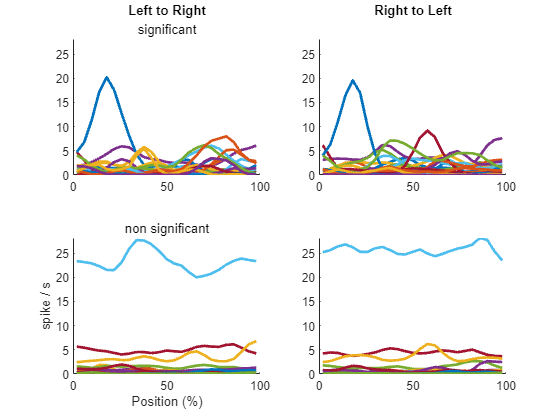

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + diff(mapsparams.Xbinedges) / 2;
m = max(Maps.map, [], 'all');

for idir = 1:2
    subplot(2,2,idir);
    plot(bincenters, squeeze(Maps.map(Maps.LLH_pval <= 0.05,idir,:))','linewidth', 2);
    set(gca,'Ylim', [0 m],'Box', 'off');
end
for idir = 1:2
    subplot(2,2,idir + 2);
    plot(bincenters, squeeze(Maps.map(Maps.LLH_pval > 0.05,idir,:))','linewidth', 2);
    set(gca,'Ylim', [0 m],'Box', 'off');
end

%labels title etc
subplot(2,2,3);
xlabel('Position (%)');
ylabel('spike / s');
subtitle('non significant')

subplot(2,2,1);
title('Left to Right');
subtitle('significant')

subplot(2,2,2);
title('Right to Left');
subtitle(' ')

Generate plots depicting the place fields and their associated standard errors for the initial two significant cells, as well as for the non-significant cells.

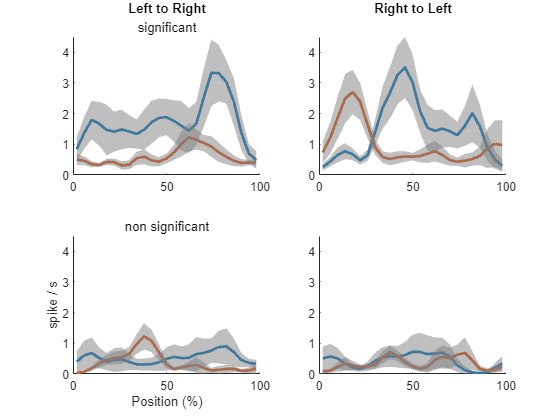

%indices of cells to plot
cellnum1 = find(Maps.LLH_pval <= 0.05, 2, 'first');
cellnum2 = find(Maps.LLH_pval > 0.05, 2, 'first');
m = max(Maps.map([cellnum1(:)' cellnum2(:)'],:,:) + Maps.map_SE([cellnum1(:)' cellnum2(:)'],:,:), [], 'all');

%Plotting place fields side by side
figure;
bincenters = mapsparams.Xbinedges(1:end-1) + diff(mapsparams.Xbinedges) / 2;

for idir = 1:2
    subplot(2,2,idir);
    plot(bincenters, squeeze(Maps.map(cellnum1,idir,:))', 'linewidth', 2);
    hold on;ciplot(bincenters, squeeze(Maps.map(cellnum1,idir,:) - Maps.map_SE(cellnum1,idir,:)), squeeze(Maps.map(cellnum1,idir,:) + Maps.map_SE(cellnum1,idir,:)))
    set(gca,'Ylim', [0 m],'Box', 'off');
end

for idir = 1:2
    subplot(2,2,idir + 2);
    plot(bincenters, squeeze(Maps.map(cellnum2,idir,:))', 'linewidth', 2);
    hold on;ciplot(bincenters, squeeze(Maps.map(cellnum2,idir,:) - Maps.map_SE(cellnum2,idir,:)), squeeze(Maps.map(cellnum2,idir,:) + Maps.map_SE(cellnum2,idir,:)))
    set(gca,'Ylim', [0 m],'Box', 'off');
end

%labels title etc
subplot(2,2,3);
xlabel('Position (%)');
ylabel('spike / s');
subtitle('non significant')

subplot(2,2,1);
title('Left to Right');
subtitle('significant')

subplot(2,2,2);
title('Right to Left');
subtitle(' ')

Plot the place fields as colored maps, ordering them according to their peak location measured in the left to right condition

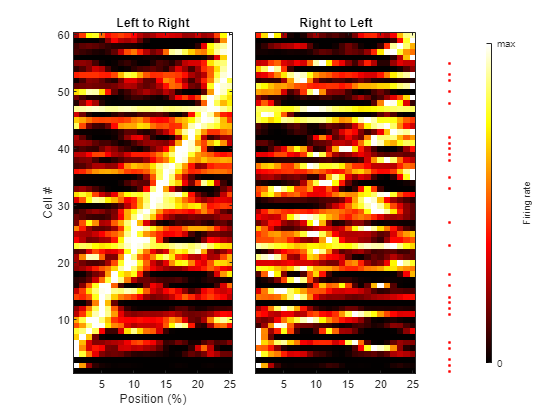

figure;

%Detecting max firing rate and peak position
[maxLtoR, peakidx] = max(Maps.map(:,2,:), [], 3);
[maxRtoL, ~] = max(Maps.map(:,1,:), [], 3);

%Normalizing place fields from 0 to max firing rate
mapXLtoR = squeeze(Maps.map(:,2,:)) ./ maxLtoR;
mapXRtoL = squeeze(Maps.map(:,1,:)) ./ maxRtoL;

%Reordering place fields according to peak position (estimated from L to R
%place fields).
[~, sortidx] = sort(peakidx, 'ascend');
mapXLtoR = mapXLtoR(sortidx,:);
mapXRtoL = mapXRtoL(sortidx,:);

%for titling
dirnames = {'Left to Right', 'Right to Left'};

%Plotting place fields normalized to max activation rate
for idir = 1:2
    subplot(1,5,(idir-1)*2 + 1:idir*2);
    if idir == 1
        imagesc(mapXLtoR);
    else
        imagesc(mapXRtoL);
    end
    set(gca,'Clim', [0 1], 'Ydir', 'normal');
    title(dirnames{idir})
    if idir == 1
        xlabel('Position (%)')
        ylabel('Cell #')
    end
    if idir == 2
        set(gca, 'Ytick', []);
    end
end
colormap(hot);

%Marking with an asterisk those with a significant place field.
subplot(1,10,9);
sigidx = find(Maps.LLH_pval <= 0.05);
plot(zeros(size(sigidx)), sigidx - 0.5, 'r.');
set(gca, 'Xtick', [], 'XColor', 'none', 'Ytick', [], 'YColor', 'none')

%Colorbar
subplot(1,10,10);
set(gca,'Visible', 'off')
c = colorbar('Location', 'west', 'Ticks', [0 1], 'TickLabels', {'0', 'max'});
c.Label.String = 'Firing rate';

### 2.1.5 Generalization of the linear approach to n dimension

How would you do update the method developped for two dimensions so that it is applicable to even more complex models with n > 2 dimensions?